# **Taller #11**

Ana María Palacio G.

**Introducción: Análisis modelo epidemiológico SIRV**

El objetivo de este taller es resolver numéricamente, usando el método numérico de Runge-Kutta que se logra mediante la implementación  de la función [**ode45**](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal.

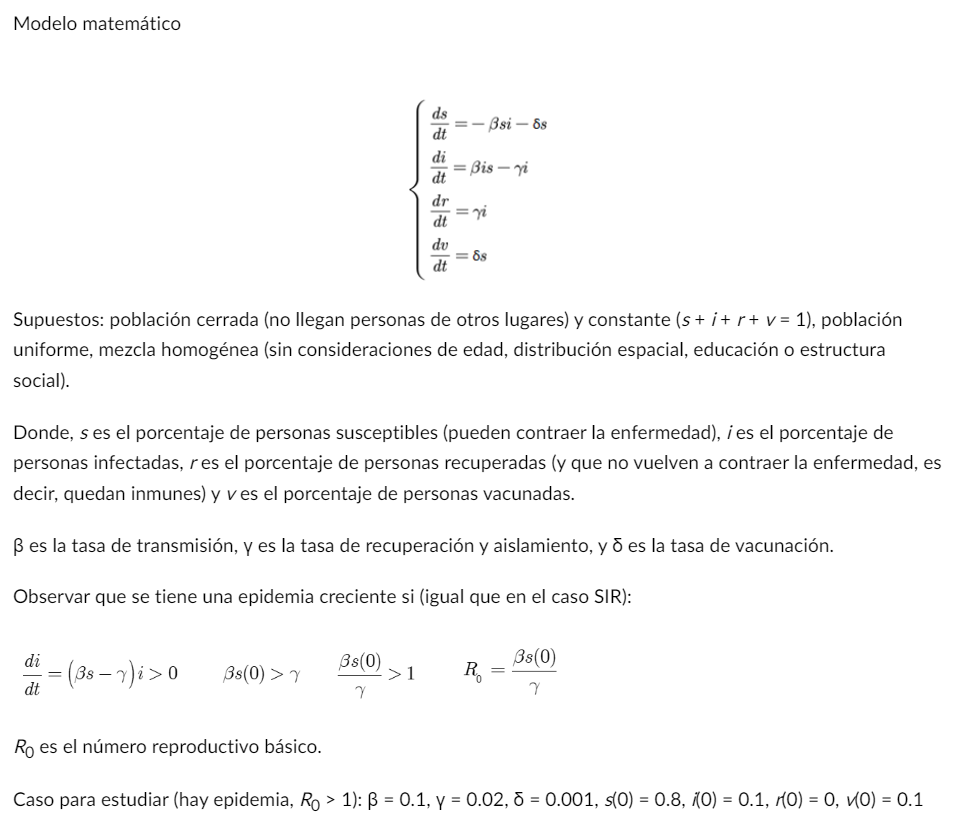

**Metodología:** Se plantean 5 puntos donde en cada uno se halla la solución simbólica con MATLAB y se realiza además, gráficas de la solución para verificar resultados. Por último, se realiza un análisis de los datos obtenidos  indicando cómo influye cada coeficiente y su variación en el comportamiento del gráfico y qué significa esto dentro del modelo epidemiológico.

Puntos a analizar:

- Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)? 

- Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

**PUNTO 1.**

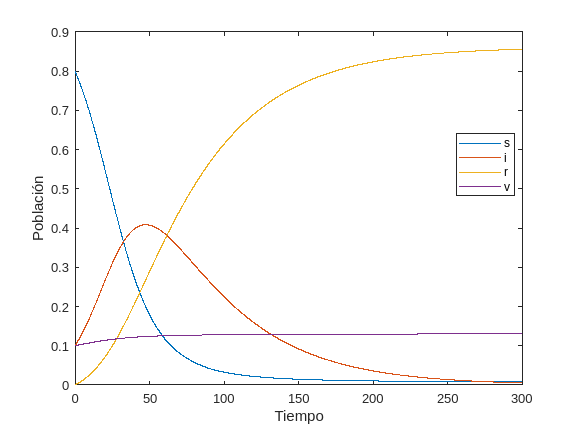

syms s(t) i(t) r(t) v(t)

beta= 0.1;
gamma= 0.02;
delta= 0.001;

ecu1= -beta*s*i -delta*s ; %suseptibles
ecu2= beta*s*i - gamma*i; %infectados
ecu3= gamma*i; %recuperados
ecu4= delta*s; %vacunados

F= odeFunction([ecu1, ecu2, ecu3, ecu4], [s i r v]);

%Tiempo
t0=0;
tf=300;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0.8, 0.1, 0, 0.1];

[t, Sol]= ode45 (F, t, CI);

s_Sol= Sol(:,1);%Es una matriz, entonces en este caso es todas las filas de la primera columna
i_Sol= Sol(:,2); %Todas las filas, segunda columna
r_Sol= Sol (:,3);
v_Sol= Sol (:,4);


%Gráfica
figure
plot(t, s_Sol)
hold on
plot (t, i_Sol)
hold on 
plot (t, r_Sol)
hold on
plot (t, v_Sol)
xlabel ("Tiempo")
ylabel ("Población")
legend ("s", "i", "r","v", "Location", "best")

**Conclusión:** 

Resultados: 

- En la gráfica se puede observar el comportamiento de un pico epidemiológico.

- Es claro que a medida que pasa el tiempo la cantidad de población suseptible disminuye.

- La tasa de recuperados aumenta debido que a medida que pasa el tiempo.

Análisis:

- Se puede observar que la tasa de suseptibles disminuye, esto es debido a que la población entra en la tasa de infectados y por esto se genera un pico. 

- Adicionalmente, los infectados pasan directamente a la tasa de recuperados, por lo que se genera en esta curva un crecimiento proporcional a la disminución en los suseptibles.

- La curva de la tasa de vacunados es pequeña debido a que el valor de esta es 0.001. un poco más del 10% de la población.

Se realiza un cambio de condiciones de delta (vacunados) para observar como cambia la tasa de infectados.

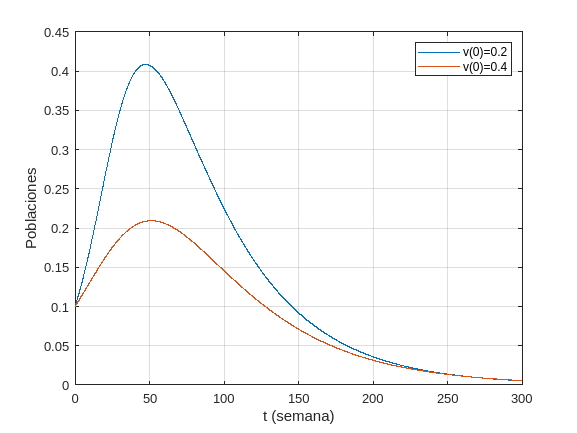

v0=0.4;

ci=[0.9-v0 0.1 0 v0];
[t2, Sol2]=ode45 (F, t, ci);
I_sol2 = Sol2 (:, 2);

figure
plot (t, i_Sol, t2, I_sol2)
xlabel ("t (semana)")
ylabel ("Poblaciones")
grid on
legend ({'v(0)=0.2', ['v(0)=' num2str(v0)]})

**Conclusión:** 

Resultados: 

- Se observa que la gráfica roja (vacunados con tasa de 0.4) tiene un menor pico de infección que la curva azul de infectados con tasa de vacunación de 0.001.

Análisis:

- Se puede observar que a medida que aumenta la tasa de vacunación al valor de 0.04 disminuye el pico de infectados en un 50% pasando el pico de infección de 0.4 de la población a 0.2.

- La tasa de vacunación ayuda a que hayan menos infectados, sin embargo a medida que pasa el tiempo se puede observar que en cualquier caso ese porcentaje tiende a disminuír.

**PUNTO 2.**

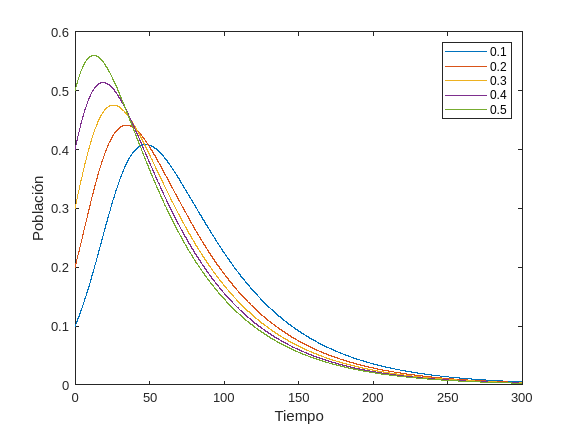

syms s(t) i(t) r(t) v(t)

beta= 0.1;
gamma= 0.02;
delta= 0.001;

ecu1= -beta*s*i -delta*s ; %suseptibles
ecu2= beta*s*i - gamma*i; %infectados
ecu3= gamma*i; %recuperados
ecu4= delta*s; %vacunados

F= odeFunction([ecu1, ecu2, ecu3, ecu4], [s i r v]);

%Tiempo
t0=0;
tf=300;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
MultipleCI= [0.8 0.1 0 0.1
             0.7 0.2 0 0.1
             0.6 0.3 0 0.1
             0.5 0.4 0 0.1
             0.4 0.5 0 0.1];

figure

for i=1:length (MultipleCI) 
    [t, Sol]= ode45 (F, t, MultipleCI(i,:)); %experimento con todos los valores de las columnas 

i_Sol= Sol(:, 2); %fijese en los valores solo de i
plot (t, i_Sol)
hold on
xlabel("Tiempo")
ylabel ("Población")
end
legend (num2str(MultipleCI(:,2))); %Esto sirve para tomar todos los valores de arriba sin tener que escribiros de a uno. tomamos

**Conclusión:** 

Resultados: 

- Se observar que a medida que se disminuye el valor de beta, es menor el pico, pero tarda un poco más en disminuír y estabilizarse.

Análisis:

- Se puede observar que a medida que se disminuye el valor de beta, es menor el porcentaje de población infectada, pero tardan un poco más en recuperarse y estabilizarse.

- Si se infecta mayor cantidad de la población (en este caso 50%) esto permitirá que el brote termine más rápido.

**PUNTO 3.**

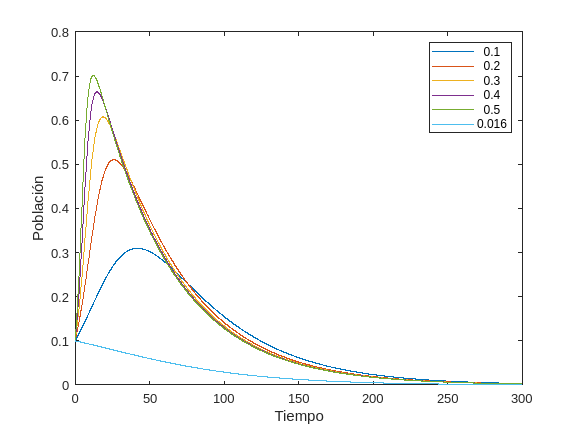

syms s(t) i(t) r(t) v(t)

beta= [0.1 0.2 0.3 0.4 0.5 0.016];
gamma= 0.02;
delta=0.01;


%Tiempo
t0=0;
tf=300;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0.8, 0.1, 0, 0.1];

figure
for beta1 = beta
ecu1= -beta1*s*i -delta*s ; 
ecu2= beta1*s*i - gamma*i; 
ecu3= gamma*i; 
ecu4= delta*s; 

F= odeFunction([ecu1, ecu2, ecu3, ecu4], [s i r v]);

[t, Sol]=ode45(F, t, CI);
i_Sol= Sol(:, 2); 
plot (t, i_Sol)
hold on
xlabel("Tiempo")
ylabel ("Población")

end
legend (num2str(beta'));

**Conclusión:** 

Resultados: 

- A medida que aumenta el valor de beta, el pico se incrementa y disminuye más rápidamente.

- La curva de beta=0.016 no genera un pico ya que su valor en >1.

- Se observa que todas las curvas comienzan en el punto de poblacción 0.1.

Análisis:

- Para hallar el valor de 0.016  se usó esta fórmula y se despejó el valor de beta. Este valor es el mínimo con el que se evitaría una pandemia sin llegar a cero.

- La curva con valor 0.016 no presenta un pico debido a que este es el mínimo valor que se puede tomar sin llegar a cero donde no se generaría un brote de la enfermedad, sino que la población se mantiene "saludable" en el tiempo.

**PUNTO 4.**

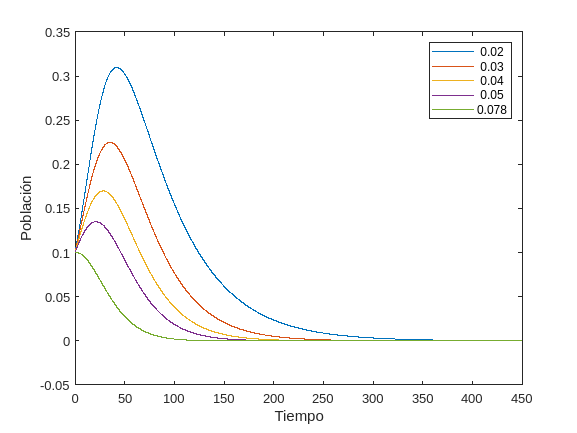

syms s(t) i(t) r(t) v(t)

beta= 0.1;
gamma= [0.02, 0.03, 0.04, 0.05, 0.078 ];
delta=0.01;


%Tiempo
t0=0;
tf=450;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0.8, 0.1, 0, 0.1];

figure
for gamma1 = gamma
ecu1= -beta*s*i -delta*s ; 
ecu2= beta*s*i - gamma1*i; 
ecu3= gamma1*i; 
ecu4= delta*s; 

F= odeFunction([ecu1, ecu2, ecu3, ecu4], [s i r v]);

[t, Sol]=ode45(F, t, CI);
i_Sol= Sol(:, 2); 
plot (t, i_Sol)
hold on
xlabel("Tiempo")
ylabel ("Población")

end
legend (num2str(gamma'));

**Conclusión:** 

Resultados: 

- A medida que disminuye el valor de gamma, el pico se incrementa y se demora más tiempo en estabilizarse.

- Se observa que todas las curvas comienzan en el punto de poblacción 0.1.

Análisis:

- Para hallar el valor de 0.078  se usó esta fórmula y se despejó el valor de gamma. Este valor es el mínimo con el que se evitaría una pandemia.

- La curva con valor 0.078 es el valor mínimo de gamma donde se evitaría una epidemia debido a que esta curva no presenta ningun pico de infección.

- A medida que disminuye el valor de gamma (recuperados) aumenta el pico de población infectada y muestra que ytarda más tiempo en salir de la enfermedad.

**PUNTO 5.**

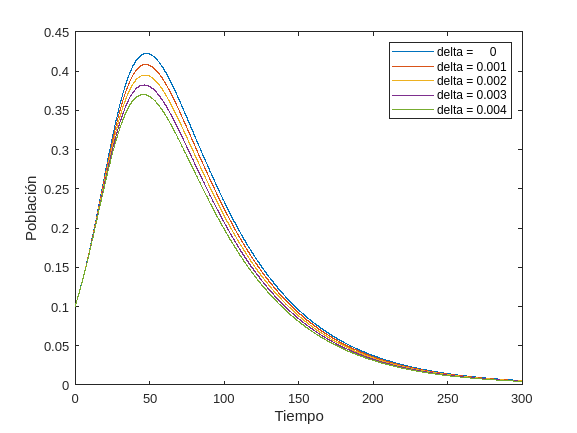

syms s(t) i(t) r(t) v(t)

%parámetros
beta = 0.1;
gamma = 0.02;
delta = [0.000, 0.001, 0.002, 0.003, 0.004];
%método númerico
t0 = 0;
tf = 300;
h = 0.1;
t = t0:h:tf;

%condiciones iniciales
CI = [0.8 0.1 0 0.1];



%solución metodo númerico
figure
for delta1 = delta
ecu1= -beta*s*i -delta1*s ; 
ecu2= beta*s*i - gamma*i; 
ecu3= gamma*i; 
ecu4= delta1*s; 

F= odeFunction([ecu1, ecu2, ecu3, ecu4], [s i r v]);

[t, Sol]=ode45(F, t, CI);
i_Sol= Sol(:, 2); 
plot (t, i_Sol)
hold on
xlabel("Tiempo")
ylabel ("Población")

end

xlabel("Tiempo")
ylabel("Población")
legend("delta = " + num2str(delta'))

**Conclusión:** 

Resultados: 

- A medida que aumenta el valor de delta, el pico de infección disminuye.

- A medida que el valor de delta aumenta, el pico de infección tarda menos tiempo en estabilizarse.

- Cuando delta=0, la gráfica se encuentra en el pico más alto de infección.

Se realiza un cambio de condiciones de delta (vacunados) para observar como cambia la tasa de infectados.

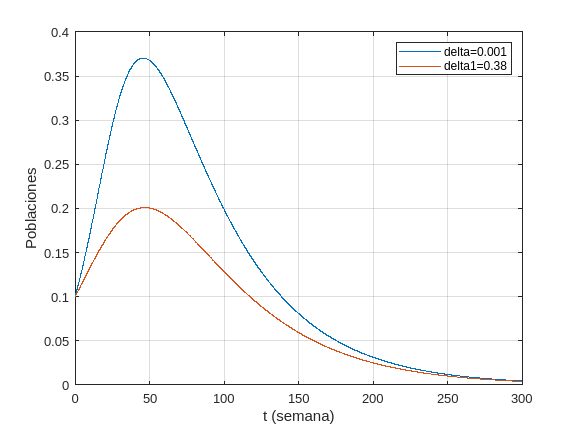

delta1=0.38;

ci=[0.9-delta1 0.1 0 v0];
[t2, Sol2]=ode45 (F, t, ci);
I_sol2 = Sol2 (:, 2);

figure
plot (t, i_Sol, t2, I_sol2)
xlabel ("t (semana)")
ylabel ("Poblaciones")
grid on
legend ({'delta=0.001', ['delta1=' num2str(delta1)]})

**Conclusión:** 

Resultados: 

- Luego de realizar un tanteo con diferentes valores de delta, se llegó a la conclusión de que el valor en el que el pico de infectados llega a 0.2 cuando delta=0.38.

- La gráfica roja (delta=0.38) se estabiliza más rápido que la gráfica delta=0.001.

Análisis

- La tasa mínima con la que se debe vacunar la población de manera que el pico de infectados llegue al valor de 0.2 es de 0.38 aproximadamente.

- A medida que aumenta el valor de delta (tasa de vacunación) disminuye el pico de infectados en la población.

- Cuando el valor de delta es más grande, el pico de infección tarda menos tiempo en estabilizarse.